Máme naměřená data vyjadřující závislost výšky a váhy lidí. Chceme udělat aproximaci těchto dat, abychom získali rovnici vyjadřující právě tuto závislost. Předpokládáme, že závislost bude přímka. 

Rovnice přímky:


$$y=k*x+q$$


kde $k$ ovlivňuje sklon a $q$ zase offset přímky. Naše přímka tedy vypadá následovně:


$$\textrm{výška}=k*\textrm{váha}+q$$
  

kde pro jednoduchost řekneme, že $k=0,64$. 

Máme tedy úlohu pouze s jedním parametrem, který chceme nastavit tak, aby aproximace byla co možná nejlepší. Takže úloha je právě ono hledání vhodného parametru.

Naše naměřená data jsou:


$$\left\lbrack \begin{array}{cccc}
\textrm{výška} & 1,4 & 1,9 & 3,2\\
\textrm{váha} & 0,5 & 2,3 & 2,9
\end{array}\right\rbrack$$


vyska = [1.4 1.9 3.2];
vaha = [0.5 2.3 2.9];
plot(vaha,vyska,"ro");
hold on;

Nejprve si musíme vytvořit tzv. **ztrátovou funkci **$E$ (Loss function). V našem případě se bude jednat o vztah vyjadřující sumu všech kvadratických rozdílů naší aproximované křivky a naměřených dat. Tento vztah se nazývá metoda nejmenších čtverců a je velmi často používána pro hledání aproximace.

#### 
$$\begin{array}{l}
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -y_{\textrm{aproximovaé}} \right)}^2 \\
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)}^2 \\
E={\left(1,4-\left(0,64*0,5+q\right)\right)}^2 +{\left(1,9-\left(0,64*2,3+q\right)\right)}^2 {\;+\;\left(3,2-\left(0,64*2,9+q\right)\right)}^2 
\end{array}$$


kde $N$je počet všech naměřených dat, a $q$ je parametr, který hledáme. Takže máme vyčíslenou ztrátovou funkci a mohu začít pátrat po optimálním řešení. Pozor! My neznáme jaká ta minimální hodnota $E$ bude, takže nelze za $E$dosadit prostě třeba hodnotu nula a analiticky dopočítat přesnou hodnotu parametru $q$.  Samozřejmě by nás také mohlo napadnout, za parametr $q$ prostě začít dosazovat náhodné čísla a s trochou štěstí bychom i nějaké jakési minimum této funkce dostali, ale my to uděláme trochu sofistikovaněji pomocí metody největšího spádu (Gradient Decent). 

Ta sofistikovanost bude následující. Využijeme totiž toho, že lokální extrémy funkce mají derivaci rovnou nule. Pokud jsme tedy v minimu naší ztrátové funkce, tak musí být její derivace rovna nule. Zde by mohl nastat problém, pokud by ztrátová funkce obsahovala více lokálních extrémů, ale jelikož je naše ztrátová funkce kvadrát odchylek, čili parabola, tak víme, že parabola obsahuje lokální extrém pouze jeden a to globální minimum, které se právě snažíme nalézt. 

Takže provedeme derivaci naší ztrátové funkce podle parametru $q$. Derivace ztrátové funkce je rovna derivaci všech jednotlivých členů sumy, tím pádem:

#### 
$$\frac{\partial E}{\partial q}=\sum_{n_0 }^N \frac{{\partial \left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)}^2 }{\partial q}=\sum_{n_0 }^N 2\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)*-1=\sum_{n_0 }^N -2\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial q}=\frac{{\partial \left(1,4-\left(0,64*0,5+q\right)\right)}^2 }{\partial q}+\frac{{\partial \left(1,9-\left(0,64*2,3+q\right)\right)}^2 }{\partial q}+\;\frac{{\partial \left(3,2-\left(0,64*2,9+q\right)\right)}^2 }{\partial q}$$


#### 
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(0,64*0,5+q\right)\right)+-2\left(1,9-\left(0,64*2,3+q\right)\right)+-2\left(3,2-\left(0,64*2,9+q\right)\right)$$


Derivace složené funkce je derivace vnitřní funkce krát derivace vnější funkce, takže výsledek je vidět výše. Takže nyní máme připravenou derivaci ztrátové funkci a můžeme začít hledat minimum. Nejdříve si zvolíme náhodnou hodnotu našeho parametru $q$. např. $q=0$ a následně zjistíme, jakou má ztrátová funkce v tomto bodě hodnotu derivace pouhým dosazením za parametr $q$. Pokud hodnota derivace v tomto bodě není nulová, tak bychom potřebovali změnit hodnotu $q$ tak, aby jsme se k minimu přiblížili. Otázka nyní zní, zda parametr zvyšovat či snižovat a o kolik. Odpoveď na tuto otázku nám dá výsledek, který jsme získali dosazením parametru $q$ do derivace ztrátové funkce. Hodnota derivace nám totiž říká, zda ztrátová funkce v tomto bodě roste (kladná hodnota derivace), nebo kelsá (záporná hodnota derivace) a velikost této hodnoty také odpovídá tomu jak rychle hodnota klesá, či roste. Takže nyní musíme ve směru (pokud ztrátová funkce v tomto bodě klesá, tak parametr zvyžuji a pokud naopak roste, tak parametr zvyšuji) upravit parametr. K jeho úpravě použijeme ještě přenásobení spočtené hodnoty derivace v daném bodě tzv. koeficientem učení $\alpha$. Koeficient učení $\alpha$ nám ovlivňuje "velikost kroku" z daného bodu do nového. Pokud volíme koeficient učení příliš malý, metodě bude déle trvat, než ke správné hodnotě dokonverguje. Pokud naopak volíme koeficient učení příliš velký, může se nám naopak stát, že metoda bude dokonce divergovat (krok se provede přes minimum do hodnoty ztrátové funcke ještě vyšší, než byla v bodě, ze kterého jsme výpočet prováděli). Koeficient učení lze zvolit tedy např. $\alpha \;=0,1$. 

Zkusme si tedy dosadit "náhodný" počáteční bod pro naše odvození derivace ztrátové funkce výše. 

####  
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(0,64*0,5+0\right)\right)+-2\left(1,9-\left(0,64*2,3+0\right)\right)+-2\left(3,2-\left(0,64*2,9+0\right)\right)=-5,7$$


Výsledkem je $-5,7$, čili víme, že musíme hodnotu parametru snížit. Koeficient učení zvolíme oněch $0,1$, tím pádem parametr nakonec bude mít hodnotu:

#### 
$$q_{\textrm{nový}} =q_{\textrm{původní}} -\left(\frac{\partial E}{\partial q}*\alpha \right)$$


#### 
$$q_{\textrm{nový}} =0-\left(\left(-5,7\right)*0,1\right)$$


#### 
$$q_{\textrm{nový}} =0,57$$


Tímto výpočtem jsem tedy získal novou hodnotu parametru $q$. Novou hodnotu opět dosadíme do odvozené derivace ztrátové funkce a zjistíme, jestli se již rovná nule. Pokud ano, výpočet je u konce a my našli optimální hodnotu parametru $q$. Pokud ale gradient není nulový, tak stejným způsobek jako výše upravíme parametr $q$. Tento proces provádíme tak dlouho, dokud parametr $q$ nebude roven nule. Přesněji řečeno se málo kdy povede nalézt přesně nulovou derivaci ztátové funkce, proto typicky volíme určitou toleranci $\tau$, při které nám již přesnost aproximace stačí. Tato tolerance může být v našem příkaldu třeba $\tau \;=0,01$.

Výpočtem bychom dostali hodnoty parametrů:

#### 
$$\begin{array}{l}
q_{\textrm{náhodný}} =0\\
q=0,57\\
q=0,8\;\\
q=0,89\\
q=0,94\\
q=0,95
\end{array}$$


Při hodnotě parametru $q=0,95$ je již derivace ztrátové funkce pouze $-0,004$. To znamená, že derivace ztrátové funkce je téměř nulová (menší než naše zvolená tolerance $0,01$). Tím pádem mohu výpočet ukončit a hodnotu parametru $q$ považovat za správnou.

Teď to celé zkusíme naházet do kódu. Data z tabulky máme již připravené z kódu nahoře, takže zde připravím jen symbolickou proměnou parametru $q$, koeficient učení $\alpha$ a toleranci $\tau$ 

alpha = 0.1;
tau = 0.01;
syms q_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((vyska - (vaha*0.64 + q_sym)).^2);

 A ztrátovou funkci derivujeme.

dE_sym = diff(E_sym,q_sym);

Nyní si ještě naplníme první parametr náhodnou hodnotou, v našem případě nulou. Pro jméno koeficientu zvolíme odlišné jméno, než pro jméno symbolické jméno koeficientu, aby nám program fungoval.

q = 0;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $\textrm{100}$.

for i = 1:100 
    dE = (double(subs(dE_sym,q_sym,q)));
    if abs(dE) < tau
        break;
    end
    q = q - dE*alpha
end

q = 0.5704

q = 0.7986

q = 0.8898

q = 0.9263

q = 0.9409

q = 0.9468

q = 0.9491

Zkusíme si aproximaci vykreslit do grafu.

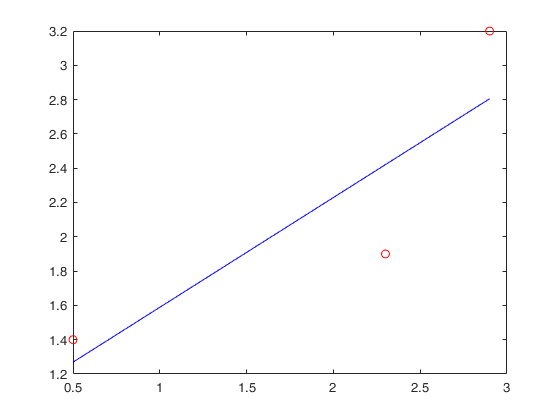

plot(vaha,0.64.*vaha + q,"b-");
hold off;

To by asi šlo. Pro zajímavost je možné si vykreslit ještě graf ztrátové funkce, a derivace ztrátové funkce.

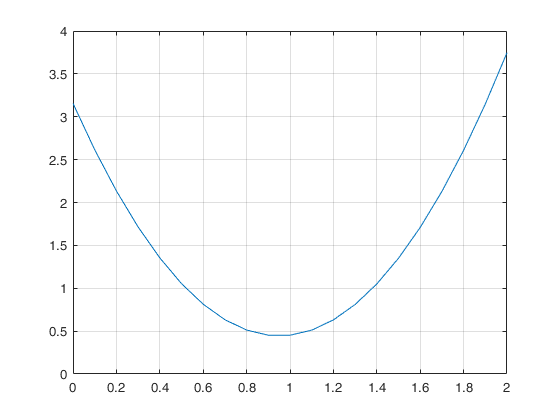

plot(0:0.1:2,double(subs(E_sym,q_sym,0:0.1:2)));
grid on;

Z grafu ztrátové funkce je patrné, že se jedná skutečně o parabolu, jak jsme předpokládali. je také vidět, že minimum má zhruba okolo těch $0,95$. Takže i výsledek naší optimalizace parametru byl úspěšný.

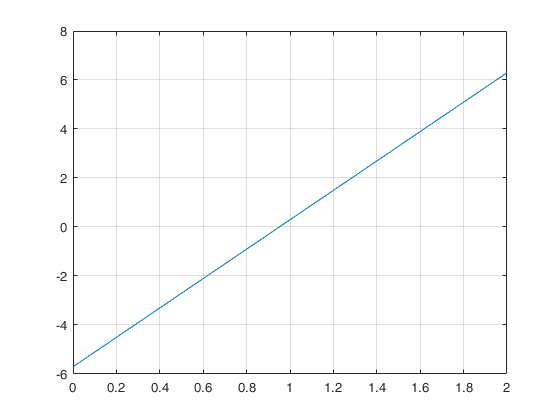

plot(0:0.1:2,double(subs(dE_sym,q_sym,0:0.1:2)));
grid on;

Z grafu derivace ztrátové funkce je pro změnu vidět, že nulové hodnoty skutečně dosahuje při oněch zhruba $0,95$ a také že pokud by parametr byl větší, tak hodnota derivace byla kladná (to by značilo, že hodnotu parametru musím snižovat) a naopak pro hodnoty menší než $0,95$ je derivace záporná, čili naznačuje, že pro dosažení nulové derivace musím naopak parametr zvyšovat. 

Tak a teď si přidáme menší komplikaci. Ta komplikace se jmenuje další parametr, konkrétně to bude parametr $k$ z naší rovnice přímky $\textrm{výška}=k*\textrm{váha}+q$. Do téhle doby byl parametr $k$ nastaven stabilně na $0,64$, ale nyní budeme provádět aproximaci na základě obou dvou parametrů zároveň.

V principu vše děláme stejně. Takže začneme vytvořením ztrátové funkce $E\ldotp$

#### 
$$\begin{array}{l}
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -y_{\textrm{aproximovaé}} \right)}^2 \\
E=\sum_{n_0 }^N {\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)}^2 \\
E={\left(1,4-\left(k*0,5+q\right)\right)}^2 +{\left(1,9-\left(k*2,3+q\right)\right)}^2 {\;+\;\left(3,2-\left(k*2,9+q\right)\right)}^2 
\end{array}$$


Vidíme že vztah pro ztrátovou funkci je naprosto stejný, jen s rozdílem, že místo konstantní hodnoty $0,64$ je nyní parametr $k$. 

Následuje derivace, ale nyní máme dva parametry, takže budeme dělat nejdříve parciální derivaci podle parametru $q$ a poté parciální derivaci podle parametru $k$. To znamená, že získám dva vztahy. Jeden vyjadřující závislost na parametru $q$, kterým budu následně tento parametr upravovat a druhý vyjadřující závislost na parametru $k$, který bude zase použit pro úpravu parametru $k$. Jinými slovy jsem vlatně spočítal gradient ztrátové funkce s ohledem na všechny její parametry. Proto se metoda jmenuje gradientní.  


$$\nabla E=\left(\frac{\partial E}{\partial q},\frac{\partial E}{\partial k}\right)$$


Parciální derivace podle parametru $q$:

#### 
$$\frac{\partial E}{\partial q}=\sum_{n_0 }^N \frac{{\partial \left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)}^2 }{\partial q}=\sum_{n_0 }^N 2\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)*-1=\sum_{n_0 }^N -2\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial q}=\frac{{\partial \left(1,4-\left(k*0,5+q\right)\right)}^2 }{\partial q}+\frac{{\partial \left(1,9-\left(k*2,3+q\right)\right)}^2 }{\partial q}+\;\frac{{\partial \left(3,2-\left(k*2,9+q\right)\right)}^2 }{\partial q}$$


#### 
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(k*0,5+q\right)\right)+-2\left(1,9-\left(k*2,3+q\right)\right)+-2\left(3,2-\left(k*2,9+q\right)\right)$$


Parciální derivace podle parametru $k$:

#### 
$$\frac{\partial E}{\partial k}=\sum_{n_0 }^N \frac{{\partial \left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)}^2 }{\partial k}=\sum_{n_0 }^N 2\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)*-x_{\textrm{naměřené}} =\sum_{n_0 }^N -2{*x}_{\textrm{naměřené}} *\left(y_{\textrm{naměřené}} -\left(k*x_{\textrm{naměřené}} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial k}=\frac{{\partial \left(1,4-\left(k*0,5+q\right)\right)}^2 }{\partial k}+\frac{{\partial \left(1,9-\left(k*2,3+q\right)\right)}^2 }{\partial k}+\;\frac{{\partial \left(3,2-\left(k*2,9+q\right)\right)}^2 }{\partial k}$$


#### 
$$\frac{\partial E}{\partial k}=$$

$$-2*0,5*\left(1,4-\left(k*0,5+q\right)\right)+-2*2,3*\left(1,9-\left(k*2,3+q\right)\right)+-2*2,9*\left(3,2-\left(k*2,9+q\right)\right)$$


Nyní, když máme gradienty úspěšně spočteny, tak můžeme postupovat zase obdobně, jako u výpočtu s jedním parametrem. To znamená, že si pro každý parametr náhodně určím hodnoty. U nás to bude $q=0$ a $k=1$. Hodnoty dosadím gradientu ztrátové funkce, čili do obou vztahů získaných pomocí parciálních derivací ztrátové funkce. 

#### 
$$\frac{\partial E}{\partial q}=-2\left(1,4-\left(1*0,5+0\right)\right)+-2\left(1,9-\left(1*2,3+0\right)\right)+-2\left(3,2-\left(1*2,9+0\right)\right)=-1,6$$


#### 
$$\frac{\partial E}{\partial k}=$$

$$-2*0,5*\left(1,4-\left(1*0,5+0\right)\right)+-2*2,3*\left(1,9-\left(1*2,3+0\right)\right)+-2*2,9*\left(3,2-\left(1*2,9+0\right)\right)=-0,8$$


S hodnotami získnými těmito dosazeními zacházím stejně jako u příkaldu s jedním parametrem. Čili hodnoty přenásobím koeficientem učení a odečítám je od původních hodnot koecicientů. **Pozor! **V tomto případě by již výpočet nefungoval pro hodnotu koeficientu učení $\alpha =0\ldotp 1$. Optimalizace těchto dvou parametrů najednou si žádá nižší krok, aby dokonvergovala k požadovanému optimu. Zvolíme tedy krok $0,01$.

#### 
$$q_{\textrm{nový}} =q_{\textrm{původní}} -\left(\frac{\partial E}{\partial q}*\alpha \right)$$


#### 
$$q_{\textrm{nový}} =0-\left(\left(-1,6\right)*0,01\right)$$


#### 
$$q_{\textrm{nový}} =0,016$$


#### 
$$q_{\textrm{nový}} =q_{\textrm{původní}} -\left(\frac{\partial E}{\partial k}*\alpha \right)$$


#### 
$$q_{\textrm{nový}} =1-\left(\left(-0,8\right)*0,01\right)$$


#### 
$$q_{\textrm{nový}} =1,008$$


Postup zase opakujeme tak dlouho, dokud nebude křivka aproximovaná podle naší zadané tolerance.

Takže to pojďme převést do kódu. Data z tabulky máme stále připravené z kódu nahoře, takže zde připravím jen symbolické proměnné parametrů $q,k$, koeficient učení $\alpha$ a toleranci $\tau$ 

alpha = 0.01;
tau = 0.01;
syms q_sym k_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((vyska - (vaha*k_sym + q_sym)).^2);

 A ztrátovou funkci derivujeme. Můžeme buď derivovat jednotlivé členy zvlášť, nebo využít funkce gradient.

%        buď takhle:
% dEdq_sym = diff(E_sym,q_sym);
% dEdk_sym = diff(E_sym,k_sym);
%        nebo takhle:
grad_E_sym = gradient(E_sym,[q_sym,k_sym]);

Nyní si ještě naplníme první parametr $q$ a $k$ náhodnými hodnotami, v našem případě $q=0,\;k=1$.

q = 0;
k = 1;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$ a $k$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $100$.

for i = 1:500 
    dEdq = (double(subs(grad_E_sym(1),[q_sym,k_sym],[q,k])));
    dEdk = (double(subs(grad_E_sym(2),[q_sym,k_sym],[q,k])));
    
    if (abs(dEdq) < tau) && (abs(dEdk) < tau)
        iter = i;
        break;
    end
    q = q - dEdq*alpha;
    k = k - dEdk*alpha;
end

Zkusíme si aproximaci vykreslit do grafu.

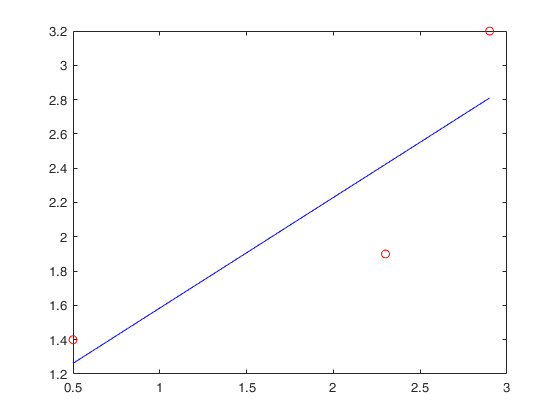

plot(vaha,vyska,"ro");
hold on;
plot(vaha,k.*vaha + q,"b-");
hold off;

To by asi taky šlo. Pro zajímavost je možné si vykreslit ještě graf ztrátové funkce, a derivace ztrátové funkce.

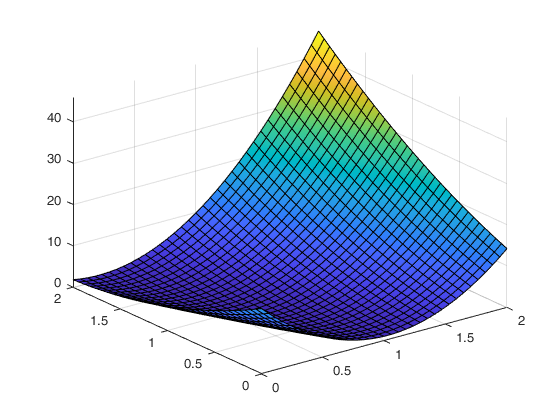

fsurf(E_sym,[0 2 0 2]);
grid on;

Na první pohled je vidět, že se jedná o 3D graf, neboď vyobrazuj ztrátovou funkci v závislosti na dvou parametrech a to $q$ a $k$.

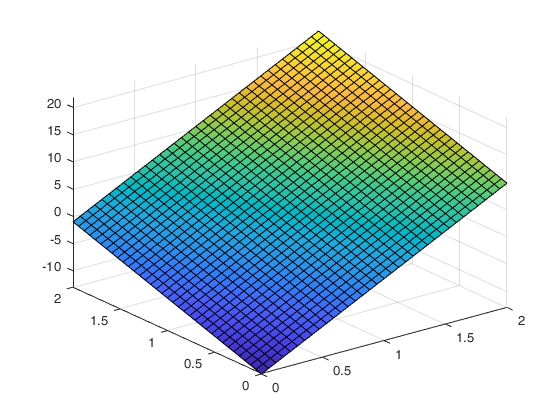

fsurf(grad_E_sym(1),[0 2 0 2]);

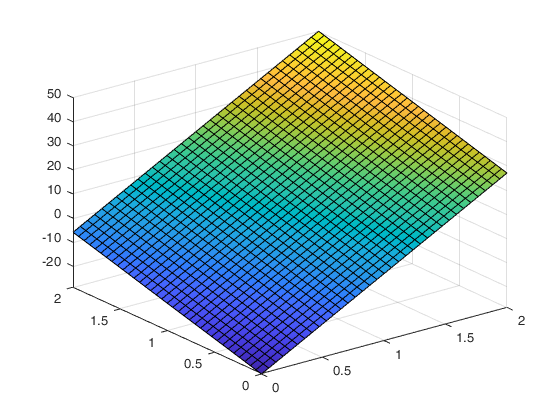

fsurf(grad_E_sym(2),[0 2 0 2]);
grid on;

Při vykreselní gradientu ztrátové funkci musíme vykreslit každou parciální derivaci zvlášť. První odpovídá parciální derivaci ztrátové funcke podle parametru $q$ a druhý zase parciální derivaci ztrátové funkce podle parametru $k$.   

Nevyhnutelná otázka je, co kdybych měl parametrů víc než dva? Např bych chtěl zadaná data proklát polynomem vyšího řádu. Postup je zase naprosto totožný. Parciálních derivací bude stejné množství, jako je parametrů a stejným způsobm optimalizuji. 

 Nejprve si tedy vytvořím parametry, které budu optimalizovat. Jejich počet je odvozen od řádu polynomu, kterým chci aproximovat.

alpha = 0.0000001;      % míra učení
tau = 0.01;             % maximální možná chyba pro ukončení výpočtu
M = 3;                  % řád polynomu
syms w_sym [1,M+1];     % příprava koeficientů v symbolické podobě

Data která jsem fitoval přímkou se mi teď nehodí, jelikož je jich málo, vytvořím si tedy jiná data. Konkrétně si nechám vygenerovat nějaký polynom čtvrtého řádu a proložím ho gausovským šumem.

func = @(x) (x.^3)+(2.*x.^2)+(-3.*x)+5;     % funkce pro nagenerování dat
from = -5;                                  % rozsah pro od ...
to = 5;                                     % do pro nagenerování dat

N =  20;                            % počet vzorků
x = from:((to-from)/(N-1)):to;      % vzorkovací čas
y = awgn(func(x),2);                % generátor naměřených dat skrze funkci pro nagenerování dat (prostě přidá do funkce šum)

Teď musím napsat zjistit ztrátovou funkci, ale k tomu potřebuju mít nadefinovaný předpis polynomu, pro který ztrátovou funkci počítám. To zajišťuje následující kód:

y_sym = sym(0);                                 % zde je provedno vytvořrní bázové funkce
syms x_sym;
for j = 0:M                                     % vypočítej přes daný řád polynomu
    y_sym = y_sym + ((w_sym(j+1))*(x_sym^j));   % podle rovnice polynomu (x^j*w_j)
end

V podstatě jsem si jen přopravil vektor $y$ který obsahuje symbolicky všechny koeficienty, ale také symbolicky vstupy.

#### 
$$y=w_1 +w_2 *x+w_3 *x^2 +\;\ldotp \ldotp \ldotp +w_M *x^M \;$$


Nyní můžeme přikročit konečně k vytvoření ztrátové funcke.

E_sym = sum((y-subs(y_sym,x_sym,x)).^2);

A teď přijde na řadu parciální derivace podle všech parametrů $w$. 

grad_E_sym = gradient(E_sym,w_sym);

Nyní všechny koeficienty nastavím na náhodné hodoty od jedné do pěti.

w = (rand(M+1,1)*5);

A nakonec samotný iterační výpočet.

for i = 1:1000 
    grad_E = double(subs(grad_E_sym,w_sym,w'));
    if (abs(max(grad_E)) < tau)
        iter = i;
        break;
    end
    w = w - grad_E*alpha
end

A je hotovo

plot(x,y,"ro");
hold on;
plot(x,Polynomial_evaluation(x,w),"b-");
hold off;